# Plan Path for a Differential Drive Robot in Simulink

## **Load the Map and Simulink Model**

Load the occupancy map, which defines the map limits and obstacles within the map. `exampleMaps.mat` contains multiple maps including `simpleMap`, which this example uses. 

load matlab.mat

a = [5 5];
b = [45 5];
c = [25 35];


m = [15 35];
n = [5 15];
o = [45 15];


p = [45 35];
q = [35 15];
r = [5 35];

## Model Overview

Open the Simulink model.

open_system('pathPlanningSimulinkModel.slx')

## **Run the Model**

simulation = sim('pathPlanningSimulinkModel.slx');

## **Visualize The Motion of Robot**

After simulating the model, visualize the robot driving the obstacle-free path in the map.

map = binaryOccupancyMap(complexMap);
%robot1
robotPose1 = simulation.Pose1;
thetaIdx = 3;
% Translation
xyz = robotPose1;
xyz(:, thetaIdx) = 0;


%robot2
robotPose2 = simulation.Pose2;
thetaIdx = 3;
% Translation
abc = robotPose2;
abc(:, thetaIdx) = 0;

%robot3
robotPose3 = simulation.Pose3;
thetaIdx = 3;
% Translation
pqr = robotPose3;
pqr(:, thetaIdx) = 0;


d = [14.5 7.5];
e = [10 15];
f = [18.33 29.25];
squareSize = 1

squareSize = 1

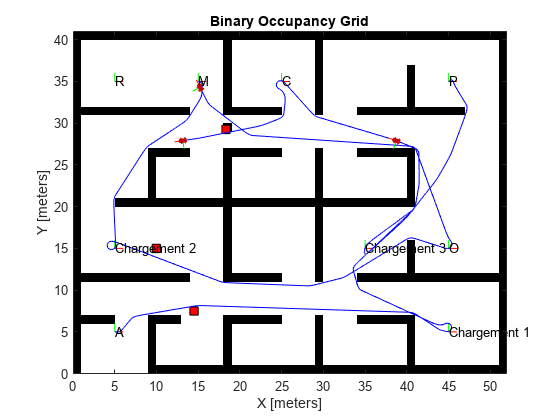


% Rotation in XYZ euler angles
theta1 = robotPose1(:,thetaIdx);
thetaEuler1 = zeros(size(robotPose1, 1), 3 * size(theta1, 2));
thetaEuler1(:, end) = theta1;


% Rotation in ABC euler angles
theta2 = robotPose2(:,thetaIdx);
thetaEuler2 = zeros(size(robotPose2, 1), 3 * size(theta2, 2));
thetaEuler2(:, end) = theta2;


% Rotation in PQR euler angles
theta3 = robotPose3(:,thetaIdx);
thetaEuler3 = zeros(size(robotPose3, 1), 3 * size(theta3, 2));
thetaEuler3(:, end) = theta3;


% Plot the robot poses at every 10th step.
for k = 1:10:size(xyz, 1) 
    show(map)

view([-0.100 90.000])
    hold on;
    
    % Plot the a location.
    plotTransforms([a, 0], eul2quat([0, 0, 0]))
    text(a(1), a(2), 2, 'A');
    % Plot the b location.
    plotTransforms([b, 0], eul2quat([0, 0, 0]))
    text(b(1), b(2), 2, 'Chargement 1');
    % Plot the c
    plotTransforms([c, 0], eul2quat([0, 0, 0]))
    text(c(1), c(2), 2, 'C');

% 
     % Plot the a location.
    plotTransforms([m, 0], eul2quat([0, 0, 0]))
    text(m(1), m(2), 2, 'M');
    % Plot the b location.
    plotTransforms([n, 0], eul2quat([0, 0, 0]))
    text(n(1), n(2), 2, 'Chargement 2');
    % Plot the c
    plotTransforms([o, 0], eul2quat([0, 0, 0]))
    text(o(1), o(2), 2, 'O');


    % Plot the a location.
    plotTransforms([p, 0], eul2quat([0, 0, 0]))
    text(p(1), p(2), 2, 'P');
    % Plot the b location.
    plotTransforms([q, 0], eul2quat([0, 0, 0]))
    text(q(1), q(2), 2, 'Chargement 3');
    % Plot the c
    plotTransforms([r, 0], eul2quat([0, 0, 0]))
    text(r(1), r(2), 2, 'R');


    rectangle('Position', [d(1)-squareSize/2, d(2)-squareSize/2, squareSize, squareSize], 'FaceColor', 'r')
    rectangle('Position', [e(1)-squareSize/2, e(2)-squareSize/2, squareSize, squareSize], 'FaceColor', 'r')
    
    rectangle('Position', [f(1)-squareSize/2, f(2)-squareSize/2, squareSize, squareSize], 'FaceColor', 'r')

       

    % Plot the xy-locations.
    plot(robotPose1(:, 1), robotPose1(:, 2), '-b')
    plot(robotPose2(:, 1), robotPose2(:, 2), '-b')
    plot(robotPose3(:, 1), robotPose3(:, 2), '-b')
    
    %Plot the robot pose as it traverses the path.
    quat1 = eul2quat(thetaEuler1(k, :), 'xyz');
    quat2 = eul2quat(thetaEuler2(k, :), 'xyz');
    quat3 = eul2quat(thetaEuler3(k, :), 'xyz');

    plotTransforms(xyz(k,:), quat1, 'MeshFilePath','groundvehicle.stl');
    plotTransforms(abc(k,:), quat2, 'MeshFilePath','groundvehicle.stl');
    plotTransforms(pqr(k,:), quat3, 'MeshFilePath','groundvehicle.stl');
    light;
    drawnow;
    hold off;
end